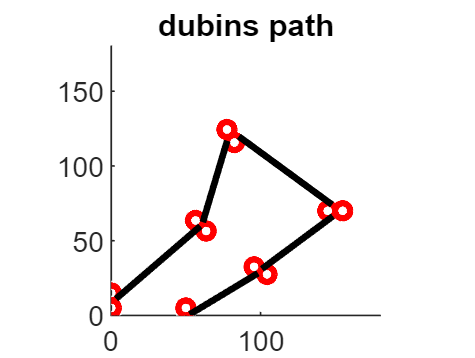

%%dubins code
%clear,clc;

%given turning radius
turning_radius = 5;

%waypoints provided
waypoints = [0 10;60 60;80 120;150 70;100 30;50 0];
heading_angles = [0;45;30;-90;-120;-180];


%Starting Circle Sets (SC)
sc_1 = starter_circle_centres(waypoints(1,1), waypoints(1,2), heading_angles(1));
sc_2 = starter_circle_centres(waypoints(2,1), waypoints(2,2), heading_angles(2));
sc_3 = starter_circle_centres(waypoints(3,1), waypoints(3,2), heading_angles(3));
sc_4 = starter_circle_centres(waypoints(4,1), waypoints(4,2), heading_angles(4));
sc_5 = starter_circle_centres(waypoints(5,1), waypoints(5,2), heading_angles(5));
SC = [sc_1;sc_2;sc_3;sc_4;sc_5;];
%Ending Circle Sets (EC)
ec_2 = final_circle_centres(waypoints(2,1), waypoints(2,2), heading_angles(2));
ec_3 = final_circle_centres(waypoints(3,1), waypoints(3,2), heading_angles(3));
ec_4 = final_circle_centres(waypoints(4,1), waypoints(4,2), heading_angles(4));
ec_5 = final_circle_centres(waypoints(5,1), waypoints(5,2), heading_angles(5));
ec_6 = final_circle_centres(waypoints(6,1), waypoints(6,2), heading_angles(6));
EC = [ec_2;ec_3;ec_4;ec_5;ec_6];

%each set sc_1 to ec_2, sc_2 to ec_3, sc_3 to ec_4, sc_4 to ec_5, sc_5 to ec_6

%%%%%-------------------------------SC1 to EC2---------------------------------------------%%%%%%

%upper circles (LSL)
UC_straight = abs(sqrt((sc_1(1,1) - ec_2(1,1))^2 + (sc_1(1,2) - ec_2(1,2))^2));
%lower circles (RSR)
LC_straight = abs(sqrt((sc_1(2,1) - ec_2(2,1))^2 + (sc_1(2,2) - ec_2(2,2))^2));
%upper to lower circles (LSR)
ULC_straight = abs(sqrt((sc_1(1,1) - ec_2(2,1))^2 + (sc_1(1,2) - ec_2(2,2))^2));
%lower to upper circles (RSL)
LUC_straight = abs(sqrt((sc_1(2,1) - ec_2(1,1))^2 + (sc_1(2,2) - ec_2(1,2))^2));

%PSY will be zero for upper circles and lower circles (LSL and RSR) 
psy_LSL = 0;
psy_RSR = 0;
psy_LSR = asind(turning_radius/ULC_straight);
psy_RSL = asind(turning_radius/LUC_straight);

%phi_e
phi_e = atan2d((waypoints(2,2) - waypoints(1,2)), (waypoints(2,1) - waypoints(1,1)));
%%-------------------------------LSL---------------------------------------------%%
%LSL 
phi_ex_LSL = phi_e + psy_LSL - 90; %exit L
phi_en_LSL = phi_e + psy_LSL - 90; %entry L
ExPx_LSL = sc_1(1,1) + 5*cosd(phi_ex_LSL); %exit L_x
ExPy_LSL = sc_1(1,2) + 5*sind(phi_ex_LSL); %exit L_y
EnPx_LSL = ec_2(1,1) + 5*cosd(phi_en_LSL); %entry L_x
EnPy_LSL = ec_2(1,2) + 5*sind(phi_en_LSL); %entry L_y
ExP_LSL = [ExPx_LSL, ExPy_LSL]; %LSL EXIT POINT
EnP_LSL = [EnPx_LSL, EnPy_LSL]; %LSL ENTRY POINT
LSL_Ex_En_tangent = sqrt((ExPx_LSL - EnPx_LSL)^2 + (ExPy_LSL - EnPy_LSL)^2);

%LSL arc length exit point
v1_lsl = [waypoints(1,1) - sc_1(1,1), waypoints(1,2) - sc_1(1,2), 0];
v2_lsl = [ExP_LSL(1,1) - sc_1(1,1), ExP_LSL(1,2) - sc_1(1,2), 0];
%checking angle is non-zero
if norm(v1_lsl) == 0 || norm(v2_lsl) == 0
    LSR_angle_ex = 0;
else
    LSR_angle_ex = atan2(norm(cross(v1_lsl,v2_lsl)), dot(v1_lsl,v2_lsl));
end
%LSL arc length ex
LSL_arc_ex = turning_radius * LSR_angle_ex;

%LSL arc length entry point
g1_lsl = [waypoints(2,1) - sc_1(2,1), waypoints(2,2) - sc_1(2,2), 0];
g2_lsl = [EnP_LSL(1,1) - sc_1(2,1), EnP_LSL(1,2) - sc_1(2,2), 0];
%checking angle is non-zero
if norm(g1_lsl) == 0 || norm(g2_lsl) == 0
    LSL_angle_en = 0;
else
    LSL_angle_en = atan2(norm(cross(g1_lsl,g2_lsl)), dot(g1_lsl,g2_lsl));
end
%LSL arc length en
LSL_arc_en = turning_radius * LSL_angle_en; 
%total LSL length
LSL_sc1_ec2 = LSL_Ex_En_tangent + LSL_arc_ex + LSL_arc_en;
%%-------------------------------LSR---------------------------------------------%%
%LSR
phi_ex_LSR = phi_e + psy_LSR - 90; %exit L
phi_en_LSR = phi_e + psy_LSR + 90; %entry R 
ExPx_LSR = sc_1(1,1) + 5*cosd(phi_ex_LSR); %exit L_x
ExPy_LSR = sc_1(1,2) + 5*sind(phi_ex_LSR); %exit L_y
EnPx_LSR = ec_2(2,1) + 5*cosd(phi_en_LSR); %entry R_x
EnPy_LSR = ec_2(2,2) + 5*sind(phi_en_LSR); %entry R_y
ExP_LSR = [ExPx_LSR, ExPy_LSR]; %LSR EXIT POINT
EnP_LSR = [EnPx_LSR, EnPy_LSR]; %LSR ENTRY POINT
LSR_Ex_En_tangent = sqrt((ExPx_LSR - EnPx_LSR)^2 + (ExPy_LSR - EnPy_LSR)^2);
%LSR arc lengths
v1_lsr = [waypoints(1,1) - sc_1(1,1), waypoints(1,2) - sc_1(1,2), 0];
v2_lsr = [ExPx_LSR(1,1) - sc_1(1,1), ExP_LSR(1,2) - sc_1(1,2), 0];
%checking angle is non-zero
if norm(v1_lsr) == 0 || norm(v2_lsr) == 0
    LSR_angle_ex = 0;
else
    LSR_angle_ex = atan2(norm(cross(v1_lsr,v2_lsr)), dot(v1_lsr,v2_lsr));
end
%LSR arc length ex
LSR_arc_ex = turning_radius * LSR_angle_ex;

%LSR arc length entry point
g1_lsr = [waypoints(2,1) - sc_1(2,1), waypoints(2,2) - sc_1(2,2), 0];
g2_lsr = [EnP_LSR(1,1) - sc_1(2,1), EnP_LSR(1,2) - sc_1(2,2), 0];
%checking angle is non-zero
if norm(g1_lsr) == 0 || norm(g2_lsr) == 0
    LSR_angle_en = 0;
else
    LSR_angle_en = atan2(norm(cross(g1_lsr,g2_lsr)), dot(g1_lsr,g2_lsr));
end
%LSL arc length en
LSR_arc_en = turning_radius * LSR_angle_en; 
%total LSL length
LSR_sc1_ec2 = LSR_Ex_En_tangent + LSR_arc_ex + LSR_arc_en;
%%-------------------------------RSR---------------------------------------------%%
%RSR
phi_ex_RSR = phi_e + psy_RSR + 90; %exit R
phi_en_RSR = phi_e + psy_RSR + 90; %entry R
ExPx_RSR = sc_1(2,1) + 5*cosd(phi_ex_RSR); %exit R_x
ExPy_RSR = sc_1(2,2) + 5*sind(phi_ex_RSR); %exit R_y
EnPx_RSR = ec_2(2,1) + 5*cosd(phi_en_RSR); %entry R_x
EnPy_RSR = ec_2(2,2) + 5*sind(phi_en_RSR); %entry R_y
ExP_RSR = [ExPx_RSR, ExPy_RSR]; %RSR EXIT POINT
EnP_RSR = [EnPx_RSR, EnPy_RSR]; %RSR ENTRY POINT
RSR_Ex_En_tangent = sqrt((ExPx_RSR - EnPx_RSR)^2 + (ExPy_RSR - EnPy_RSR)^2);
%RSR arc lengths
v1_rsr = [waypoints(1,1) - sc_1(1,1), waypoints(1,2) - sc_1(1,2), 0];
v2_rsr = [ExPx_RSR(1,1) - sc_1(1,1), ExP_RSR(1,2) - sc_1(1,2), 0];
%checking angle is non-zero
if norm(v1_rsr) == 0 || norm(v2_rsr) == 0
    RSR_angle_ex = 0;
else
    RSR_angle_ex = atan2(norm(cross(v1_rsr,v2_rsr)), dot(v1_rsr,v2_rsr));
end
%RSR arc length ex
RSR_arc_ex = turning_radius * RSR_angle_ex;

%RSR arc length entry point
g1_rsr = [waypoints(2,1) - sc_1(2,1), waypoints(2,2) - sc_1(2,2), 0];
g2_rsr = [EnP_RSR(1,1) - sc_1(2,1), EnP_RSR(1,2) - sc_1(2,2), 0];
%checking angle is non-zero
if norm(g1_rsr) == 0 || norm(g2_rsr) == 0
    RSR_angle_en = 0;
else
    RSR_angle_en = atan2(norm(cross(g1_rsr,g2_rsr)), dot(g1_rsr,g2_rsr));
end
%LSL arc length en
RSR_arc_en = turning_radius * RSR_angle_en; 
%total LSL length
RSR_sc1_ec2 = RSR_Ex_En_tangent + RSR_arc_ex + RSR_arc_en;
%%-------------------------------RSL---------------------------------------------%%
%RSL
phi_ex_RSL = phi_e + psy_RSL + 90; %exit R
phi_en_RSL = phi_e + psy_RSL - 90; %entry R
ExPx_RSL = sc_1(2,1) + 5*cosd(phi_ex_RSL); %exit R_x
ExPy_RSL = sc_1(2,2) + 5*sind(phi_ex_RSL); %exit R_y
EnPx_RSL = ec_2(1,1) + 5*cosd(phi_en_RSL); %entry L_x
EnPy_RSL = ec_2(1,2) + 5*sind(phi_en_RSL); %entry L_y
ExP_RSL = [ExPx_RSL, ExPy_RSL]; %RSL EXIT POINT
EnP_RSL = [EnPx_RSL, EnPy_RSL]; %RSL ENTRY POINT
RSL_Ex_En_tangent = sqrt((ExPx_RSL - EnPx_RSL)^2 + (ExPy_RSL - EnPy_RSL)^2);
%RSR arc lengths
v1_rsl = [waypoints(1,1) - sc_1(1,1), waypoints(1,2) - sc_1(1,2), 0];
v2_rsl = [ExPx_RSL(1,1) - sc_1(1,1), ExP_RSL(1,2) - sc_1(1,2), 0];
%checking angle is non-zero
if norm(v1_rsl) == 0 || norm(v2_rsl) == 0
    RSL_angle_ex = 0;
else
    RSL_angle_ex = atan2(norm(cross(v1_rsl,v2_rsl)), dot(v1_rsl,v2_rsl));
end
%RSL arc length ex
RSL_arc_ex = turning_radius * RSL_angle_ex;

%RSL arc length entry point
g1_rsl = [waypoints(2,1) - sc_1(2,1), waypoints(2,2) - sc_1(2,2), 0];
g2_rsl = [EnP_RSL(1,1) - sc_1(2,1), EnP_RSL(1,2) - sc_1(2,2), 0];
%checking angle is non-zero
if norm(g1_rsl) == 0 || norm(g2_rsl) == 0
    RSL_angle_en = 0;
else
    RSL_angle_en = atan2(norm(cross(g1_rsl,g2_rsl)), dot(g1_rsl,g2_rsl));
end
%LSL arc length en
RSL_arc_en = turning_radius * RSL_angle_en;
%total LSL length
RSL_sc1_ec2 = RSL_Ex_En_tangent + RSL_arc_ex + RSL_arc_en;

%%sort which is smallest path to choose
sc1_ec2_path_name = {'LSL', 'LSR', 'RSL', 'RSR'};
sc1_ec2_path = [LSL_sc1_ec2, LSR_sc1_ec2, RSL_sc1_ec2, RSR_sc1_ec2];
[optimal_sc1_ec2, idx] = sort(sc1_ec2_path, 'ascend');
sc1_ec2 = sc1_ec2_path_name(idx);
sc1_ec2(2,:) = num2cell(optimal_sc1_ec2);


%%%%%-------------------------------SC2 to EC3---------------------------------------------%%%%%%

%upper circles (LSL)
UC_straight_1 = abs(sqrt((sc_2(1,1) - ec_3(1,1))^2 + (sc_2(1,2) - ec_3(1,2))^2));
%lower circles (RSR)
LC_straight_1 = abs(sqrt((sc_2(2,1) - ec_3(2,1))^2 + (sc_2(2,2) - ec_3(2,2))^2));
%upper to lower circles (LSR)
ULC_straight_1 = abs(sqrt((sc_2(1,1) - ec_3(2,1))^2 + (sc_2(1,2) - ec_3(2,2))^2));
%lower to upper circles (RSL)
LUC_straight_1 = abs(sqrt((sc_2(2,1) - ec_3(1,1))^2 + (sc_2(2,2) - ec_3(1,2))^2));

%PSY will be zero for upper circles and lower circles (LSL and RSR) 
psy_LSL_1 = 0;
psy_RSR_1 = 0;
psy_LSR_1 = asind(turning_radius/ULC_straight_1);
psy_RSL_1 = asind(turning_radius/LUC_straight_1);

%phi_e
phi_e_1 = atan2d((waypoints(3,2) - waypoints(2,2)), (waypoints(3,1) - waypoints(2,1)));
%%-------------------------------LSL---------------------------------------------%%
%LSL 
phi_ex_LSL_1 = phi_e_1 + psy_LSL_1 - 90; %exit L
phi_en_LSL_1 = phi_e_1 + psy_LSL_1 - 90; %entry L
ExPx_LSL_1 = sc_2(1,1) + 5*cosd(phi_ex_LSL_1); %exit L_x
ExPy_LSL_1 = sc_2(1,2) + 5*sind(phi_ex_LSL_1); %exit L_y
EnPx_LSL_1 = ec_3(1,1) + 5*cosd(phi_en_LSL_1); %entry L_x
EnPy_LSL_1 = ec_3(1,2) + 5*sind(phi_en_LSL_1); %entry L_y
ExP_LSL_1 = [ExPx_LSL_1, ExPy_LSL_1]; %LSL EXIT POINT
EnP_LSL_1 = [EnPx_LSL_1, EnPy_LSL_1]; %LSL ENTRY POINT
LSL_Ex_En_tangent_1 = sqrt((ExPx_LSL_1 - EnPx_LSL_1)^2 + (ExPy_LSL_1 - EnPy_LSL_1)^2);

%LSL arc length exit point
v1_lsl_1 = [waypoints(2,1) - sc_2(1,1), waypoints(2,2) - sc_2(1,2), 0];
v2_lsl_1 = [ExP_LSL_1(1,1) - sc_2(1,1), ExP_LSL_1(1,2) - sc_2(1,2), 0];
%checking angle is non-zero
if norm(v1_lsl_1) == 0 || norm(v2_lsl_1) == 0
    LSR_angle_ex_1 = 0;
else
    LSR_angle_ex_1 = atan2(norm(cross(v1_lsl_1,v2_lsl_1)), dot(v1_lsl_1,v2_lsl_1));
end
%LSL arc length ex
LSL_arc_ex_1 = turning_radius * LSR_angle_ex_1;

%LSL arc length entry point
g1_lsl_1 = [waypoints(3,1) - sc_2(2,1), waypoints(3,2) - sc_2(2,2), 0];
g2_lsl_1 = [EnP_LSL_1(1,1) - sc_2(2,1), EnP_LSL_1(1,2) - sc_2(2,2), 0];
%checking angle is non-zero
if norm(g1_lsl_1) == 0 || norm(g2_lsl_1) == 0
    LSL_angle_en_1 = 0;
else
    LSL_angle_en_1 = atan2(norm(cross(g1_lsl_1,g2_lsl_1)), dot(g1_lsl_1,g2_lsl_1));
end
%LSL arc length en
LSL_arc_en_1 = turning_radius * LSL_angle_en_1; 
%total LSL length
LSL_sc2_ec3 = LSL_Ex_En_tangent_1 + LSL_arc_ex_1 + LSL_arc_en_1;
%%-------------------------------LSR---------------------------------------------%%
%LSR
phi_ex_LSR_1 = phi_e_1 + psy_LSR_1 - 90; %exit L
phi_en_LSR_1 = phi_e_1 + psy_LSR_1 + 90; %entry R 
ExPx_LSR_1 = sc_2(1,1) + 5*cosd(phi_ex_LSR_1); %exit L_x
ExPy_LSR_1 = sc_2(1,2) + 5*sind(phi_ex_LSR_1); %exit L_y
EnPx_LSR_1 = ec_3(2,1) + 5*cosd(phi_en_LSR_1); %entry R_x
EnPy_LSR_1 = ec_3(2,2) + 5*sind(phi_en_LSR_1); %entry R_y
ExP_LSR_1 = [ExPx_LSR_1, ExPy_LSR_1]; %LSR EXIT POINT
EnP_LSR_1 = [EnPx_LSR_1, EnPy_LSR_1]; %LSR ENTRY POINT
LSR_Ex_En_tangent_1 = sqrt((ExPx_LSR_1 - EnPx_LSR_1)^2 + (ExPy_LSR_1 - EnPy_LSR_1)^2);
%LSR arc lengths
v1_lsr_1 = [waypoints(2,1) - sc_2(1,1), waypoints(2,2) - sc_2(1,2), 0];
v2_lsr_1 = [ExP_LSR_1(1,1) - sc_2(1,1), ExP_LSR_1(1,2) - sc_2(1,2), 0];
%checking angle is non-zero
if norm(v1_lsr_1) == 0 || norm(v2_lsr_1) == 0
    LSR_angle_ex_1 = 0;
else
    LSR_angle_ex_1 = atan2(norm(cross(v1_lsr_1,v2_lsr_1)), dot(v1_lsr_1,v2_lsr_1));
end
%LSR arc length ex
LSR_arc_ex_1 = turning_radius * LSR_angle_ex_1;

%LSR arc length entry point
g1_lsr_1 = [waypoints(3,1) - sc_2(2,1), waypoints(3,2) - sc_2(2,2), 0];
g2_lsr_1 = [EnP_LSR_1(1,1) - sc_2(2,1), EnP_LSR_1(1,2) - sc_2(2,2), 0];
%checking angle is non-zero
if norm(g1_lsr_1) == 0 || norm(g2_lsr_1) == 0
    LSR_angle_en_1 = 0;
else
    LSR_angle_en_1 = atan2(norm(cross(g1_lsr_1,g2_lsr_1)), dot(g1_lsr_1,g2_lsr_1));
end
%LSL arc length en
LSR_arc_en_1 = turning_radius * LSR_angle_en_1; 
%total LSL length
LSR_sc2_ec3 = LSR_Ex_En_tangent_1 + LSR_arc_ex_1 + LSR_arc_en_1;
%%-------------------------------RSR---------------------------------------------%%
%RSR
phi_ex_RSR_1 = phi_e_1 + psy_RSR_1 + 90; %exit R
phi_en_RSR_1 = phi_e_1 + psy_RSR_1 + 90; %entry R
ExPx_RSR_1 = sc_2(2,1) + 5*cosd(phi_ex_RSR_1); %exit R_x
ExPy_RSR_1 = sc_2(2,2) + 5*sind(phi_ex_RSR_1); %exit R_y
EnPx_RSR_1 = ec_3(2,1) + 5*cosd(phi_en_RSR_1); %entry R_x
EnPy_RSR_1 = ec_3(2,2) + 5*sind(phi_en_RSR_1); %entry R_y
ExP_RSR_1 = [ExPx_RSR_1, ExPy_RSR_1]; %RSR EXIT POINT
EnP_RSR_1 = [EnPx_RSR_1, EnPy_RSR_1]; %RSR ENTRY POINT
RSR_Ex_En_tangent_1 = sqrt((ExPx_RSR_1 - EnPx_RSR_1)^2 + (ExPy_RSR_1 - EnPy_RSR_1)^2);
%RSR arc lengthsq
v1_rsr_1 = [waypoints(2,1) - sc_2(1,1), waypoints(1,2) - sc_2(1,2), 0];
v2_rsr_1 = [ExP_RSR_1(1,1) - sc_2(1,1), ExP_RSR_1(1,2) - sc_2(1,2), 0];
%checking angle is non-zero
if norm(v1_rsr_1) == 0 || norm(v2_rsr_1) == 0
    RSR_angle_ex_1 = 0;
else
    RSR_angle_ex_1 = atan2(norm(cross(v1_rsr_1,v2_rsr_1)), dot(v1_rsr_1,v2_rsr_1));
end
%RSR arc length ex
RSR_arc_ex_1 = turning_radius * RSR_angle_ex_1;

%RSR arc length entry point
g1_rsr_1 = [waypoints(3,1) - sc_2(2,1), waypoints(3,2) - sc_2(2,2), 0];
g2_rsr_1 = [EnP_RSR_1(1,1) - sc_2(2,1), EnP_RSR_1(1,2) - sc_2(2,2), 0];
%checking angle is non-zero
if norm(g1_rsr_1) == 0 || norm(g2_rsr_1) == 0
    RSR_angle_en_1 = 0;
else
    RSR_angle_en_1 = atan2(norm(cross(g1_rsr_1,g2_rsr_1)), dot(g1_rsr_1,g2_rsr_1));
end
%LSL arc length en
RSR_arc_en_1 = turning_radius * RSR_angle_en_1; 
%total LSL length
RSR_sc2_ec3 = RSR_Ex_En_tangent_1 + RSR_arc_ex_1 + RSR_arc_en_1;
%%-------------------------------RSL---------------------------------------------%%
%RSL
phi_ex_RSL_1 = phi_e_1 + psy_RSL_1 + 90; %exit R
phi_en_RSL_1 = phi_e_1 + psy_RSL_1 - 90; %entry R
ExPx_RSL_1 = sc_2(2,1) + 5*cosd(phi_ex_RSL_1); %exit R_x
ExPy_RSL_1 = sc_2(2,2) + 5*sind(phi_ex_RSL_1); %exit R_y
EnPx_RSL_1 = ec_3(1,1) + 5*cosd(phi_en_RSL_1); %entry L_x
EnPy_RSL_1 = ec_3(1,2) + 5*sind(phi_en_RSL_1); %entry L_y
ExP_RSL_1 = [ExPx_RSL_1, ExPy_RSL_1]; %RSL EXIT POINT
EnP_RSL_1 = [EnPx_RSL_1, EnPy_RSL_1]; %RSL ENTRY POINT
RSL_Ex_En_tangent_1 = sqrt((ExPx_RSL_1 - EnPx_RSL_1)^2 + (ExPy_RSL_1 - EnPy_RSL_1)^2);
%RSR arc lengths
v1_rsl_1 = [waypoints(2,1) - sc_2(1,1), waypoints(2,2) - sc_2(1,2), 0];
v2_rsl_1 = [ExPx_RSL_1(1,1) - sc_2(1,1), ExP_RSL_1(1,2) - sc_2(1,2), 0];
%checking angle is non-zero
if norm(v1_rsl_1) == 0 || norm(v2_rsl_1) == 0
    RSL_angle_ex_1 = 0;
else
    RSL_angle_ex_1 = atan2(norm(cross(v1_rsl_1,v2_rsl_1)), dot(v1_rsl_1,v2_rsl_1));
end
%RSL arc length ex
RSL_arc_ex_1 = turning_radius * RSL_angle_ex_1;

%RSL arc length entry point
g1_rsl_1 = [waypoints(3,1) - sc_2(2,1), waypoints(3,2) - sc_2(2,2), 0];
g2_rsl_1 = [EnP_RSL_1(1,1) - sc_2(2,1), EnP_RSL_1(1,2) - sc_2(2,2), 0];
%checking angle is non-zero
if norm(g1_rsl_1) == 0 || norm(g2_rsl_1) == 0
    RSL_angle_en_1 = 0;
else
    RSL_angle_en_1 = atan2(norm(cross(g1_rsl_1,g2_rsl_1)), dot(g1_rsl_1,g2_rsl_1));
end
%LSL arc length en
RSL_arc_en_1 = turning_radius * RSL_angle_en_1;
%total LSL length
RSL_sc2_ec3 = RSL_Ex_En_tangent_1 + RSL_arc_ex_1 + RSL_arc_en_1;

%%sort which is smallest path to choose
sc2_ec3_path_name = {'LSL', 'LSR', 'RSL', 'RSR'};
sc2_ec3_path = [LSL_sc2_ec3, LSR_sc2_ec3, RSL_sc2_ec3, RSR_sc2_ec3];
[optimal_sc2_ec3, idx1] = sort(sc2_ec3_path, 'ascend');
sc2_ec3 = sc2_ec3_path_name(idx1);
sc2_ec3(2,:) = num2cell(optimal_sc2_ec3);

%%%%%-------------------------------SC3 to EC4---------------------------------------------%%%%%%

%upper circles (LSL)
UC_straight_2 = abs(sqrt((sc_3(1,1) - ec_4(1,1))^2 + (sc_3(1,2) - ec_4(1,2))^2));
%lower circles (RSR)
LC_straight_2 = abs(sqrt((sc_3(2,1) - ec_4(2,1))^2 + (sc_3(2,2) - ec_4(2,2))^2));
%upper to lower circles (LSR)
ULC_straight_2 = abs(sqrt((sc_3(1,1) - ec_4(2,1))^2 + (sc_3(1,2) - ec_4(2,2))^2));
%lower to upper circles (RSL)
LUC_straight_2 = abs(sqrt((sc_3(2,1) - ec_4(1,1))^2 + (sc_3(2,2) - ec_4(1,2))^2));

%PSY will be zero for upper circles and lower circles (LSL and RSR) 
psy_LSL_2 = 0;
psy_RSR_2 = 0;
psy_LSR_2 = asind(turning_radius/ULC_straight_2);
psy_RSL_2 = asind(turning_radius/LUC_straight_2);

%phi_e
phi_e_2 = atan2d((waypoints(4,2) - waypoints(3,2)), (waypoints(4,1) - waypoints(3,1)));
%%-------------------------------LSL---------------------------------------------%%
%LSL 
phi_ex_LSL_2 = phi_e_2 + psy_LSL_2 - 90; %exit L
phi_en_LSL_2 = phi_e_2 + psy_LSL_2 - 90; %entry L
ExPx_LSL_2 = sc_3(1,1) + 5*cosd(phi_ex_LSL_2); %exit L_x
ExPy_LSL_2 = sc_3(1,2) + 5*sind(phi_ex_LSL_2); %exit L_y
EnPx_LSL_2 = ec_4(1,1) + 5*cosd(phi_en_LSL_2); %entry L_x
EnPy_LSL_2 = ec_4(1,2) + 5*sind(phi_en_LSL_2); %entry L_y
ExP_LSL_2 = [ExPx_LSL_2, ExPy_LSL_2]; %LSL EXIT POINT
EnP_LSL_2 = [EnPx_LSL_2, EnPy_LSL_2]; %LSL ENTRY POINT
LSL_Ex_En_tangent_2 = sqrt((ExPx_LSL_2 - EnPx_LSL_2)^2 + (ExPy_LSL_2 - EnPy_LSL_2)^2);

%LSL arc length exit point
v1_lsl_2 = [waypoints(3,1) - sc_3(1,1), waypoints(3,2) - sc_3(1,2), 0];
v2_lsl_2 = [ExP_LSL_2(1,1) - sc_3(1,1), ExP_LSL_2(1,2) - sc_3(1,2), 0];
%checking angle is non-zero
if norm(v1_lsl_2) == 0 || norm(v2_lsl_2) == 0
    LSR_angle_ex_2 = 0;
else
    LSR_angle_ex_2 = atan2(norm(cross(v1_lsl_2,v2_lsl_2)), dot(v1_lsl_2,v2_lsl_2));
end
%LSL arc length ex
LSL_arc_ex_2 = turning_radius * LSR_angle_ex_2;

%LSL arc length entry point
g1_lsl_2 = [waypoints(4,1) - sc_3(2,1), waypoints(4,2) - sc_3(2,2), 0];
g2_lsl_2 = [EnP_LSL_2(1,1) - sc_3(2,1), EnP_LSL_2(1,2) - sc_3(2,2), 0];
%checking angle is non-zero
if norm(g1_lsl_2) == 0 || norm(g2_lsl_2) == 0
    LSL_angle_en_2 = 0;
else
    LSL_angle_en_2 = atan2(norm(cross(g1_lsl_2,g2_lsl_2)), dot(g1_lsl_2,g2_lsl_2));
end
%LSL arc length en
LSL_arc_en_2 = turning_radius * LSL_angle_en_2; 
%total LSL length
LSL_sc3_ec4 = LSL_Ex_En_tangent_2 + LSL_arc_ex_2 + LSL_arc_en_2;
%%-------------------------------LSR---------------------------------------------%%
%LSR
phi_ex_LSR_2 = phi_e_2 + psy_LSR_2 - 90; %exit L
phi_en_LSR_2 = phi_e_2 + psy_LSR_2 + 90; %entry R 
ExPx_LSR_2 = sc_3(1,1) + 5*cosd(phi_ex_LSR_2); %exit L_x
ExPy_LSR_2 = sc_3(1,2) + 5*sind(phi_ex_LSR_2); %exit L_y
EnPx_LSR_2 = ec_4(2,1) + 5*cosd(phi_en_LSR_2); %entry R_x
EnPy_LSR_2 = ec_4(2,2) + 5*sind(phi_en_LSR_2); %entry R_y
ExP_LSR_2 = [ExPx_LSR_2, ExPy_LSR_2]; %LSR EXIT POINT
EnP_LSR_2 = [EnPx_LSR_2, EnPy_LSR_2]; %LSR ENTRY POINT
LSR_Ex_En_tangent_2 = sqrt((ExPx_LSR_2 - EnPx_LSR_2)^2 + (ExPy_LSR_2 - EnPy_LSR_2)^2);
%LSR arc lengths
v1_lsr_2 = [waypoints(3,1) - sc_3(1,1), waypoints(3,2) - sc_3(1,2), 0];
v2_lsr_2 = [ExP_LSR_2(1,1) - sc_3(1,1), ExP_LSR_2(1,2) - sc_3(1,2), 0];
%checking angle is non-zero
if norm(v1_lsr_2) == 0 || norm(v2_lsr_2) == 0
    LSR_angle_ex_2 = 0;
else
    LSR_angle_ex_2 = atan2(norm(cross(v1_lsr_2,v2_lsr_2)), dot(v1_lsr_2,v2_lsr_2));
end
%LSR arc length ex
LSR_arc_ex_2 = turning_radius * LSR_angle_ex_2;
%LSR arc length entry point
g1_lsr_2 = [waypoints(4,1) - sc_3(2,1), waypoints(4,2) - sc_3(2,2), 0];
g2_lsr_2 = [EnP_LSR_2(1,1) - sc_3(2,1), EnP_LSR_2(1,2) - sc_3(2,2), 0];
%checking angle is non-zero
if norm(g1_lsr_2) == 0 || norm(g2_lsr_2) == 0
    LSR_angle_en_2 = 0;
else
    LSR_angle_en_2 = atan2(norm(cross(g1_lsr_2,g2_lsr_2)), dot(g1_lsr_2,g2_lsr_2));
end
%LSL arc length en
LSR_arc_en_2 = turning_radius * LSR_angle_en_2; 
%total LSL length
LSR_sc3_ec4 = LSR_Ex_En_tangent_2 + LSR_arc_ex_2 + LSR_arc_en_2;
%%-------------------------------RSR---------------------------------------------%%
%RSR
phi_ex_RSR_2 = phi_e_2 + psy_RSR_2 + 90; %exit R
phi_en_RSR_2 = phi_e_2 + psy_RSR_2 + 90; %entry R
ExPx_RSR_2 = sc_3(2,1) + 5*cosd(phi_ex_RSR_2); %exit R_x
ExPy_RSR_2 = sc_3(2,2) + 5*sind(phi_ex_RSR_2); %exit R_y
EnPx_RSR_2 = ec_4(2,1) + 5*cosd(phi_en_RSR_2); %entry R_x
EnPy_RSR_2 = ec_4(2,2) + 5*sind(phi_en_RSR_2); %entry R_y
ExP_RSR_2 = [ExPx_RSR_2, ExPy_RSR_2]; %RSR EXIT POINT
EnP_RSR_2 = [EnPx_RSR_2, EnPy_RSR_2]; %RSR ENTRY POINT
RSR_Ex_En_tangent_2 = sqrt((ExPx_RSR_2 - EnPx_RSR_2)^2 + (ExPy_RSR_2 - EnPy_RSR_2)^2);
%RSR arc lengthsq
v1_rsr_2 = [waypoints(3,1) - sc_3(1,1), waypoints(3,2) - sc_3(1,2), 0];
v2_rsr_2 = [ExP_RSR_2(1,1) - sc_3(1,1), ExP_RSR_2(1,2) - sc_3(1,2), 0];
%checking angle is non-zero
if norm(v1_rsr_2) == 0 || norm(v2_rsr_2) == 0
    RSR_angle_ex_2 = 0;
else
    RSR_angle_ex_2 = atan2(norm(cross(v1_rsr_2,v2_rsr_2)), dot(v1_rsr_2,v2_rsr_2));
end
%RSR arc length ex
RSR_arc_ex_2 = turning_radius * RSR_angle_ex_2;

%RSR arc length entry point
g1_rsr_2 = [waypoints(4,1) - sc_3(2,1), waypoints(4,2) - sc_3(2,2), 0];
g2_rsr_2 = [EnP_RSR_2(1,1) - sc_3(2,1), EnP_RSR_2(1,2) - sc_3(2,2), 0];
%checking angle is non-zero
if norm(g1_rsr_2) == 0 || norm(g2_rsr_2) == 0
    RSR_angle_en_2 = 0;
else
    RSR_angle_en_2 = atan2(norm(cross(g1_rsr_2,g2_rsr_2)), dot(g1_rsr_2,g2_rsr_2));
end
%LSL arc length en
RSR_arc_en_2 = turning_radius * RSR_angle_en_2; 
%total LSL length
RSR_sc3_ec4 = RSR_Ex_En_tangent_2 + RSR_arc_ex_2 + RSR_arc_en_2;
%%-------------------------------RSL---------------------------------------------%%
%RSL
phi_ex_RSL_2 = phi_e_2 + psy_RSL_2 + 90; %exit R
phi_en_RSL_2 = phi_e_2 + psy_RSL_2 - 90; %entry L
ExPx_RSL_2 = sc_3(2,1) + 5*cosd(phi_ex_RSL_2); %exit R_x
ExPy_RSL_2 = sc_3(2,2) + 5*sind(phi_ex_RSL_2); %exit R_y
EnPx_RSL_2 = ec_4(1,1) + 5*cosd(phi_en_RSL_2); %entry L_x
EnPy_RSL_2 = ec_4(1,2) + 5*sind(phi_en_RSL_2); %entry L_y
ExP_RSL_2 = [ExPx_RSL_2, ExPy_RSL_2]; %RSL EXIT POINT
EnP_RSL_2 = [EnPx_RSL_2, EnPy_RSL_2]; %RSL ENTRY POINT
RSL_Ex_En_tangent_2 = sqrt((ExPx_RSL_2 - EnPx_RSL_2)^2 + (ExPy_RSL_2 - EnPy_RSL_2)^2);
%RSR arc lengths
v1_rsl_2 = [waypoints(3,1) - sc_3(1,1), waypoints(3,2) - sc_3(1,2), 0];
v2_rsl_2 = [ExP_RSL_2(1,1) - sc_3(1,1), ExP_RSL_2(1,2) - sc_3(1,2), 0];
%checking angle is non-zero
if norm(v1_rsl_2) == 0 || norm(v2_rsl_2) == 0
    RSL_angle_ex_2 = 0;
else
    RSL_angle_ex_2 = atan2(norm(cross(v1_rsl_2,v2_rsl_2)), dot(v1_rsl_2,v2_rsl_2));
end
%RSL arc length ex
RSL_arc_ex_2 = turning_radius * RSL_angle_ex_2;

%RSL arc length entry point
g1_rsl_2 = [waypoints(4,1) - sc_3(2,1), waypoints(4,2) - sc_3(2,2), 0];
g2_rsl_2 = [EnP_RSL_2(1,1) - sc_3(2,1), EnP_RSL_2(1,2) - sc_3(2,2), 0];
%checking angle is non-zero
if norm(g1_rsl_2) == 0 || norm(g2_rsl_2) == 0
    RSL_angle_en_2 = 0;
else
    RSL_angle_en_2 = atan2(norm(cross(g1_rsl_2,g2_rsl_2)), dot(g1_rsl_2,g2_rsl_2));
end
%LSL arc length en
RSL_arc_en_2 = turning_radius * RSL_angle_en_2;
%total LSL length
RSL_sc3_ec4 = RSL_Ex_En_tangent_2 + RSL_arc_ex_2 + RSL_arc_en_2;

%%sort which is smallest path to choose
sc3_ec4_path_name = {'LSL', 'LSR', 'RSL', 'RSR'};
sc3_ec4_path = [LSL_sc3_ec4, LSR_sc3_ec4, RSL_sc3_ec4, RSR_sc3_ec4];
[optimal_sc3_ec4, idx2] = sort(sc3_ec4_path, 'ascend');
sc3_ec4 = sc3_ec4_path_name(idx2);
sc3_ec4(2,:) = num2cell(optimal_sc3_ec4);

%%%%%-------------------------------SC4 to EC5---------------------------------------------%%%%%%

%upper circles (LSL)
UC_straight_3 = abs(sqrt((sc_4(1,1) - ec_5(1,1))^2 + (sc_4(1,2) - ec_5(1,2))^2));
%lower circles (RSR)
LC_straight_3 = abs(sqrt((sc_4(2,1) - ec_5(2,1))^2 + (sc_4(2,2) - ec_5(2,2))^2));
%upper to lower circles (LSR)
ULC_straight_3 = abs(sqrt((sc_4(1,1) - ec_5(2,1))^2 + (sc_4(1,2) - ec_5(2,2))^2));
%lower to upper circles (RSL)
LUC_straight_3 = abs(sqrt((sc_4(2,1) - ec_5(1,1))^2 + (sc_4(2,2) - ec_5(1,2))^2));

%PSY will be zero for upper circles and lower circles (LSL and RSR) 
psy_LSL_3 = 0;
psy_RSR_3 = 0;
psy_LSR_3 = asind(turning_radius/ULC_straight_3);
psy_RSL_3 = asind(turning_radius/LUC_straight_3);

%phi_e
phi_e_3 = atan2d((waypoints(5,2) - waypoints(4,2)), (waypoints(5,1) - waypoints(4,1)));
%%-------------------------------LSL---------------------------------------------%%
%LSL 
phi_ex_LSL_3 = phi_e_3 + psy_LSL_3 - 90; %exit L
phi_en_LSL_3 = phi_e_3 + psy_LSL_3 - 90; %entry L
ExPx_LSL_3 = sc_4(1,1) + 5*cosd(phi_ex_LSL_3); %exit L_x
ExPy_LSL_3 = sc_4(1,2) + 5*sind(phi_ex_LSL_3); %exit L_y
EnPx_LSL_3 = ec_5(1,1) + 5*cosd(phi_en_LSL_3); %entry L_x
EnPy_LSL_3 = ec_5(1,2) + 5*sind(phi_en_LSL_3); %entry L_y
ExP_LSL_3 = [ExPx_LSL_3, ExPy_LSL_3]; %LSL EXIT POINT
EnP_LSL_3 = [EnPx_LSL_3, EnPy_LSL_3]; %LSL ENTRY POINT
LSL_Ex_En_tangent_3 = sqrt((ExPx_LSL_3 - EnPx_LSL_3)^2 + (ExPy_LSL_3 - EnPy_LSL_3)^2);
%LSL arc length exit point
v1_lsl_3 = [waypoints(4,1) - sc_4(1,1), waypoints(4,2) - sc_4(1,2), 0];
v2_lsl_3 = [ExP_LSL_3(1,1) - sc_4(1,1), ExP_LSL_3(1,2) - sc_4(1,2), 0];
%checking angle is non-zero
if norm(v1_lsl_3) == 0 || norm(v2_lsl_3) == 0
    LSR_angle_ex_3 = 0;
else
    LSR_angle_ex_3 = atan2(norm(cross(v1_lsl_3,v2_lsl_3)), dot(v1_lsl_3,v2_lsl_3));
end
%LSL arc length ex
LSL_arc_ex_3 = turning_radius * LSR_angle_ex_3;

%LSL arc length entry point
g1_lsl_3 = [waypoints(5,1) - sc_4(2,1), waypoints(5,2) - sc_4(2,2), 0];
g2_lsl_3 = [EnP_LSL_3(1,1) - sc_4(2,1), EnP_LSL_3(1,2) - sc_4(2,2), 0];
%checking angle is non-zero
if norm(g1_lsl_3) == 0 || norm(g2_lsl_3) == 0
    LSL_angle_en_3 = 0;
else
    LSL_angle_en_3 = atan2(norm(cross(g1_lsl_3,g2_lsl_3)), dot(g1_lsl_3,g2_lsl_3));
end
%LSL arc length en
LSL_arc_en_3 = turning_radius * LSL_angle_en_3; 
%total LSL length
LSL_sc4_ec5 = LSL_Ex_En_tangent_3 + LSL_arc_ex_3 + LSL_arc_en_3;
%%-------------------------------LSR---------------------------------------------%%
%LSR
phi_ex_LSR_3 = phi_e_3 + psy_LSR_3 - 90; %exit L
phi_en_LSR_3 = phi_e_3 + psy_LSR_3 + 90; %entry R
ExPx_LSR_3 = sc_4(1,1) + 5*cosd(phi_ex_LSR_3); %exit L_x
ExPy_LSR_3 = sc_4(1,2) + 5*sind(phi_ex_LSR_3); %exit L_y
EnPx_LSR_3 = ec_5(2,1) + 5*cosd(phi_en_LSR_3); %entry R_x
EnPy_LSR_3 = ec_5(2,2) + 5*sind(phi_en_LSR_3); %entry R_y
ExP_LSR_3 = [ExPx_LSR_3, ExPy_LSR_3]; %LSR EXIT POINT
EnP_LSR_3 = [EnPx_LSR_3, EnPy_LSR_3]; %LSR ENTRY POINT
LSR_Ex_En_tangent_3 = sqrt((ExPx_LSR_3 - EnPx_LSR_3)^2 + (ExPy_LSR_3 - EnPy_LSR_3)^2);
%LSR arc lengths
v1_lsr_3 = [waypoints(4,1) - sc_4(1,1), waypoints(4,2) - sc_4(1,2), 0];
v2_lsr_3 = [ExP_LSR_3(1,1) - sc_4(1,1), ExP_LSR_3(1,2) - sc_4(1,2), 0];
%checking angle is non-zero
if norm(v1_lsr_3) == 0 || norm(v2_lsr_3) == 0
    LSR_angle_ex_3 = 0;
else
    LSR_angle_ex_3 = atan2(norm(cross(v1_lsr_3,v2_lsr_3)), dot(v1_lsr_3,v2_lsr_3));
end
%LSR arc length ex
LSR_arc_ex_3 = turning_radius * LSR_angle_ex_3;
%LSR arc length entry point
g1_lsr_3 = [waypoints(5,1) - sc_4(2,1), waypoints(5,2) - sc_4(2,2), 0];
g2_lsr_3 = [EnP_LSR_3(1,1) - sc_4(2,1), EnP_LSR_3(1,2) - sc_4(2,2), 0];
%checking angle is non-zero
if norm(g1_lsr_3) == 0 || norm(g2_lsr_3) == 0
    LSR_angle_en_3 = 0;
else
    LSR_angle_en_3 = atan2(norm(cross(g1_lsr_3,g2_lsr_3)), dot(g1_lsr_3,g2_lsr_3));
end
%LSL arc length en
LSR_arc_en_3 = turning_radius * LSR_angle_en_3; 
%total LSL length
LSR_sc4_ec5 = LSR_Ex_En_tangent_3 + LSR_arc_ex_3 + LSR_arc_en_3;
%%-------------------------------RSR---------------------------------------------%%
%RSR
phi_ex_RSR_3 = phi_e_3 + psy_RSR_3 + 90; %exit R
phi_en_RSR_3 = phi_e_3 + psy_RSR_3 + 90; %entry R
ExPx_RSR_3 = sc_4(2,1) + 5*cosd(phi_ex_RSR_3); %exit R_x
ExPy_RSR_3 = sc_4(2,2) + 5*sind(phi_ex_RSR_3); %exit R_y
EnPx_RSR_3 = ec_5(2,1) + 5*cosd(phi_en_RSR_3); %entry R_x
EnPy_RSR_3 = ec_5(2,2) + 5*sind(phi_en_RSR_3); %entry R_y
ExP_RSR_3 = [ExPx_RSR_3, ExPy_RSR_3]; %RSR EXIT POINT
EnP_RSR_3 = [EnPx_RSR_3, EnPy_RSR_3]; %RSR ENTRY POINT
RSR_Ex_En_tangent_3 = sqrt((ExPx_RSR_3 - EnPx_RSR_3)^2 + (ExPy_RSR_3 - EnPy_RSR_3)^2);
%RSR arc lengthsq
v1_rsr_3 = [waypoints(4,1) - sc_4(1,1), waypoints(4,2) - sc_4(1,2), 0];
v2_rsr_3 = [ExP_RSR_3(1,1) - sc_4(1,1), ExP_RSR_3(1,2) - sc_4(1,2), 0];
%checking angle is non-zero
if norm(v1_rsr_3) == 0 || norm(v2_rsr_3) == 0
    RSR_angle_ex_3 = 0;
else
    RSR_angle_ex_3 = atan2(norm(cross(v1_rsr_3,v2_rsr_3)), dot(v1_rsr_3,v2_rsr_3));
end
%RSR arc length ex
RSR_arc_ex_3 = turning_radius * RSR_angle_ex_3;

%RSR arc length entry point
g1_rsr_3 = [waypoints(5,1) - sc_4(2,1), waypoints(5,2) - sc_4(2,2), 0];
g2_rsr_3 = [EnP_RSR_3(1,1) - sc_4(2,1), EnP_RSR_3(1,2) - sc_4(2,2), 0];
%checking angle is non-zero
if norm(g1_rsr_3) == 0 || norm(g2_rsr_3) == 0
    RSR_angle_en_3 = 0;
else
    RSR_angle_en_3 = atan2(norm(cross(g1_rsr_3,g2_rsr_3)), dot(g1_rsr_3,g2_rsr_3));
end
%LSL arc length en
RSR_arc_en_3 = turning_radius * RSR_angle_en_3; 
%total LSL length
RSR_sc4_ec5 = RSR_Ex_En_tangent_3 + RSR_arc_ex_3 + RSR_arc_en_3;
%%-------------------------------RSL---------------------------------------------%%
%RSL
phi_ex_RSL_3 = phi_e_3 + psy_RSL_3 + 90; %exit R
phi_en_RSL_3 = phi_e_3 + psy_RSL_3 - 90; %entry L
ExPx_RSL_3 = sc_4(2,1) + 5*cosd(phi_ex_RSL_3); %exit R_x
ExPy_RSL_3 = sc_4(2,2) + 5*sind(phi_ex_RSL_3); %exit R_y
EnPx_RSL_3 = ec_5(1,1) + 5*cosd(phi_en_RSL_3); %entry L_x
EnPy_RSL_3 = ec_5(1,2) + 5*sind(phi_en_RSL_3); %entry L_y
ExP_RSL_3 = [ExPx_RSL_3, ExPy_RSL_3]; %RSL EXIT POINT
EnP_RSL_3 = [EnPx_RSL_3, EnPy_RSL_3]; %RSL ENTRY POINT
RSL_Ex_En_tangent_3 = sqrt((ExPx_RSL_3 - EnPx_RSL_3)^2 + (ExPy_RSL_3 - EnPy_RSL_3)^2);
%RSR arc lengths
v1_rsl_3 = [waypoints(4,1) - sc_4(1,1), waypoints(4,2) - sc_4(1,2), 0];
v2_rsl_3 = [ExP_RSL_3(1,1) - sc_4(1,1), ExP_RSL_3(1,2) - sc_4(1,2), 0];
%checking angle is non-zero
if norm(v1_rsl_3) == 0 || norm(v2_rsl_3) == 0
    RSL_angle_ex_3 = 0;
else
    RSL_angle_ex_3 = atan2(norm(cross(v1_rsl_3,v2_rsl_3)), dot(v1_rsl_3,v2_rsl_3));
end
%RSL arc length ex
RSL_arc_ex_3 = turning_radius * RSL_angle_ex_3;

%RSL arc length entry point
g1_rsl_3 = [waypoints(5,1) - sc_4(2,1), waypoints(5,2) - sc_4(2,2), 0];
g2_rsl_3 = [EnP_RSL_3(1,1) - sc_4(2,1), EnP_RSL_3(1,2) - sc_4(2,2), 0];
%checking angle is non-zero
if norm(g1_rsl_3) == 0 || norm(g2_rsl_3) == 0
    RSL_angle_en_3 = 0;
else
    RSL_angle_en_3 = atan2(norm(cross(g1_rsl_3,g2_rsl_3)), dot(g1_rsl_3,g2_rsl_3));
end
%LSL arc length en
RSL_arc_en_3 = turning_radius * RSL_angle_en_3;
%total LSL length
RSL_sc4_ec5 = RSL_Ex_En_tangent_3 + RSL_arc_ex_3 + RSL_arc_en_3;

%%sort which is smallest path to choose
sc4_ec5_path_name = {'LSL', 'LSR', 'RSL', 'RSR'};
sc4_ec5_path = [LSL_sc4_ec5, LSR_sc4_ec5, RSL_sc4_ec5, RSR_sc4_ec5];
[optimal_sc4_ec5, idx3] = sort(sc4_ec5_path, 'ascend');
sc4_ec5 = sc4_ec5_path_name(idx3);
sc4_ec5(2,:) = num2cell(optimal_sc4_ec5);

%%%%%-------------------------------SC5 to EC6---------------------------------------------%%%%%%

%upper circles (LSL)
UC_straight_4 = abs(sqrt((sc_5(1,1) - ec_6(1,1))^2 + (sc_5(1,2) - ec_6(1,2))^2));
%lower circles (RSR)
LC_straight_4 = abs(sqrt((sc_5(2,1) - ec_6(2,1))^2 + (sc_5(2,2) - ec_6(2,2))^2));
%upper to lower circles (LSR)
ULC_straight_4 = abs(sqrt((sc_5(1,1) - ec_6(2,1))^2 + (sc_5(1,2) - ec_6(2,2))^2));
%lower to upper circles (RSL)
LUC_straight_4 = abs(sqrt((sc_5(2,1) - ec_6(1,1))^2 + (sc_5(2,2) - ec_6(1,2))^2));

%PSY will be zero for upper circles and lower circles (LSL and RSR) 
psy_LSL_4 = 0;
psy_RSR_4 = 0;
psy_LSR_4 = asind(turning_radius/ULC_straight_4);
psy_RSL_4 = asind(turning_radius/LUC_straight_4);

%phi_e
phi_e_4 = atan2d((waypoints(6,2) - waypoints(5,2)), (waypoints(6,1) - waypoints(5,1)));
%%-------------------------------LSL---------------------------------------------%%
%LSL 
phi_ex_LSL_4 = phi_e_4 + psy_LSL_4 - 90; %exit L
phi_en_LSL_4 = phi_e_4 + psy_LSL_4 - 90; %entry L
ExPx_LSL_4 = sc_5(1,1) + 5*cosd(phi_ex_LSL_4); %exit L_x
ExPy_LSL_4 = sc_5(1,2) + 5*sind(phi_ex_LSL_4); %exit L_y
EnPx_LSL_4 = ec_6(1,1) + 5*cosd(phi_en_LSL_4); %entry L_x
EnPy_LSL_4 = ec_6(1,2) + 5*sind(phi_en_LSL_4); %entry L_y
ExP_LSL_4 = [ExPx_LSL_4, ExPy_LSL_4]; %LSL EXIT POINT
EnP_LSL_4 = [EnPx_LSL_4, EnPy_LSL_4]; %LSL ENTRY POINT
LSL_Ex_En_tangent_4 = sqrt((ExPx_LSL_4 - EnPx_LSL_4)^2 + (ExPy_LSL_4 - EnPy_LSL_4)^2);
%LSL arc length exit point
v1_lsl_4 = [waypoints(5,1) - sc_5(1,1), waypoints(5,2) - sc_5(1,2), 0];
v2_lsl_4 = [ExP_LSL_4(1,1) - sc_5(1,1), ExP_LSL_4(1,2) - sc_5(1,2), 0];
%checking angle is non-zero
if norm(v1_lsl_4) == 0 || norm(v2_lsl_4) == 0
    LSR_angle_ex_4 = 0;
else
    LSR_angle_ex_4 = atan2(norm(cross(v1_lsl_4,v2_lsl_4)), dot(v1_lsl_4,v2_lsl_4));
end
%LSL arc length ex
LSL_arc_ex_4 = turning_radius * LSR_angle_ex_4;

%LSL arc length entry point
g1_lsl_4 = [waypoints(6,1) - sc_5(2,1), waypoints(6,2) - sc_5(2,2), 0];
g2_lsl_4 = [EnP_LSL_4(1,1) - sc_5(2,1), EnP_LSL_4(1,2) - sc_5(2,2), 0];
%checking angle is non-zero
if norm(g1_lsl_4) == 0 || norm(g2_lsl_4) == 0
    LSL_angle_en_4 = 0;
else
    LSL_angle_en_4 = atan2(norm(cross(g1_lsl_4,g2_lsl_4)), dot(g1_lsl_4,g2_lsl_4));
end
%LSL arc length en
LSL_arc_en_4 = turning_radius * LSL_angle_en_4; 
%total LSL length
LSL_sc5_ec6 = LSL_Ex_En_tangent_4 + LSL_arc_ex_4 + LSL_arc_en_4;
%%-------------------------------LSR---------------------------------------------%%
%LSR
phi_ex_LSR_4 = phi_e_4 + psy_LSR_4 - 90; %exit L
phi_en_LSR_4 = phi_e_4 + psy_LSR_4 + 90; %entry R 
ExPx_LSR_4 = sc_5(1,1) + 5*cosd(phi_ex_LSR_4); %exit L_x
ExPy_LSR_4 = sc_5(1,2) + 5*sind(phi_ex_LSR_4); %exit L_y
EnPx_LSR_4 = ec_6(2,1) + 5*cosd(phi_en_LSR_4); %entry R_x
EnPy_LSR_4 = ec_6(2,2) + 5*sind(phi_en_LSR_4); %entry R_y
ExP_LSR_4 = [ExPx_LSR_4, ExPy_LSR_4]; %LSR EXIT POINT
EnP_LSR_4 = [EnPx_LSR_4, EnPy_LSR_4]; %LSR ENTRY POINT
LSR_Ex_En_tangent_4 = sqrt((ExPx_LSR_4 - EnPx_LSR_4)^2 + (ExPy_LSR_4 - EnPy_LSR_4)^2);
%LSR arc lengths
v1_lsr_4 = [waypoints(5,1) - sc_5(1,1), waypoints(5,2) - sc_5(1,2), 0];
v2_lsr_4 = [ExPx_LSR_4(1,1) - sc_5(1,1), ExP_LSR_4(1,2) - sc_5(1,2), 0];
%checking angle is non-zero
if norm(v1_lsr_4) == 0 || norm(v2_lsr_4) == 0
    LSR_angle_ex_4 = 0;
else
    LSR_angle_ex_4 = atan2(norm(cross(v1_lsr_4,v2_lsr_4)), dot(v1_lsr_4,v2_lsr_4));
end
%LSR arc length ex
LSR_arc_ex_4 = turning_radius * LSR_angle_ex_4;
%LSR arc length entry point
g1_lsr_4 = [waypoints(5,1) - sc_4(2,1), waypoints(5,2) - sc_4(2,2), 0];
g2_lsr_4 = [EnP_LSR_4(1,1) - sc_4(2,1), EnP_LSR_4(1,2) - sc_4(2,2), 0];
%checking angle is non-zero
if norm(g1_lsr_4) == 0 || norm(g2_lsr_4) == 0
    LSR_angle_en_4 = 0;
else
    LSR_angle_en_4 = atan2(norm(cross(g1_lsr_4,g2_lsr_4)), dot(g1_lsr_4,g2_lsr_4));
end
%LSL arc length en
LSR_arc_en_4 = turning_radius * LSR_angle_en_4; 
%total LSL length
LSR_sc5_ec6 = LSR_Ex_En_tangent_4 + LSR_arc_ex_4 + LSR_arc_en_4;
%%-------------------------------RSR---------------------------------------------%%
%RSR
phi_ex_RSR_4 = phi_e_4 + psy_RSR_4 + 90; %exit R
phi_en_RSR_4 = phi_e_4 + psy_RSR_4 + 90; %entry R
ExPx_RSR_4 = sc_5(2,1) + 5*cosd(phi_ex_RSR_4); %exit R_x
ExPy_RSR_4 = sc_5(2,2) + 5*sind(phi_ex_RSR_4); %exit R_y
EnPx_RSR_4 = ec_6(2,1) + 5*cosd(phi_en_RSR_4); %entry R_x
EnPy_RSR_4 = ec_6(2,2) + 5*sind(phi_en_RSR_4); %entry R_y
ExP_RSR_4 = [ExPx_RSR_4, ExPy_RSR_4]; %RSR EXIT POINT
EnP_RSR_4 = [EnPx_RSR_4, EnPy_RSR_4]; %RSR ENTRY POINT
RSR_Ex_En_tangent_4 = sqrt((ExPx_RSR_4 - EnPx_RSR_4)^2 + (ExPy_RSR_4 - EnPy_RSR_4)^2);
%RSR arc lengths
v1_rsr_4 = [waypoints(5,1) - sc_5(1,1), waypoints(5,2) - sc_5(1,2), 0];
v2_rsr_4 = [ExPx_RSR_4(1,1) - sc_5(1,1), ExP_RSR_4(1,2) - sc_5(1,2), 0];
%checking angle is non-zero
if norm(v1_rsr_4) == 0 || norm(v2_rsr_4) == 0
    RSR_angle_ex_4 = 0;
else
    RSR_angle_ex_4 = atan2(norm(cross(v1_rsr_4,v2_rsr_4)), dot(v1_rsr_4,v2_rsr_4));
end
%RSR arc length ex
RSR_arc_ex_4 = turning_radius * RSR_angle_ex_4;

%RSR arc length entry point
g1_rsr_4 = [waypoints(6,1) - sc_5(2,1), waypoints(6,2) - sc_5(2,2), 0];
g2_rsr_4 = [EnP_RSR_4(1,1) - sc_5(2,1), EnP_RSR_4(1,2) - sc_5(2,2), 0];
%checking angle is non-zero
if norm(g1_rsr_4) == 0 || norm(g2_rsr_4) == 0
    RSR_angle_en_4 = 0;
else
    RSR_angle_en_4 = atan2(norm(cross(g1_rsr_4,g2_rsr_4)), dot(g1_rsr_4,g2_rsr_4));
end
%LSL arc length en
RSR_arc_en_4 = turning_radius * RSR_angle_en_4; 
%total LSL length
RSR_sc5_ec6 = RSR_Ex_En_tangent_4 + RSR_arc_ex_4 + RSR_arc_en_4;
%%-------------------------------RSL---------------------------------------------%%
%RSL
phi_ex_RSL_4 = phi_e_4 + psy_RSL_4 + 90; %exit R
phi_en_RSL_4 = phi_e_4 + psy_RSL_4 - 90; %entry R
ExPx_RSL_4 = sc_5(2,1) + 5*cosd(phi_ex_RSL_4); %exit R_x
ExPy_RSL_4 = sc_5(2,2) + 5*sind(phi_ex_RSL_4); %exit R_y
EnPx_RSL_4 = ec_6(1,1) + 5*cosd(phi_en_RSL_4); %entry L_x
EnPy_RSL_4 = ec_6(1,2) + 5*sind(phi_en_RSL_4); %entry L_y
ExP_RSL_4 = [ExPx_RSL_4, ExPy_RSL_4]; %RSL EXIT POINT
EnP_RSL_4 = [EnPx_RSL_4, EnPy_RSL_4]; %RSL ENTRY POINT
RSL_Ex_En_tangent_4 = sqrt((ExPx_RSL_4 - EnPx_RSL_4)^2 + (ExPy_RSL_4 - EnPy_RSL_4)^2);
%RSR arc lengths
v1_rsl_4 = [waypoints(5,1) - sc_5(1,1), waypoints(5,2) - sc_5(1,2), 0];
v2_rsl_4 = [ExPx_RSL_4(1,1) - sc_5(1,1), ExP_RSL_4(1,2) - sc_5(1,2), 0];
%checking angle is non-zero
if norm(v1_rsl_4) == 0 || norm(v2_rsl_4) == 0
    RSL_angle_ex_4 = 0;
else
    RSL_angle_ex_4 = atan2(norm(cross(v1_rsl_4,v2_rsl_4)), dot(v1_rsl_4,v2_rsl_4));
end
%RSL arc length ex
RSL_arc_ex_4 = turning_radius * RSL_angle_ex_4;

%RSL arc length entry point
g1_rsl_4 = [waypoints(6,1) - sc_5(2,1), waypoints(6,2) - sc_5(2,2), 0];
g2_rsl_4 = [EnP_RSL_4(1,1) - sc_5(2,1), EnP_RSL_4(1,2) - sc_5(2,2), 0];
%checking angle is non-zero
if norm(g1_rsl_4) == 0 || norm(g2_rsl_4) == 0
    RSL_angle_en_4 = 0;
else
    RSL_angle_en_4 = atan2(norm(cross(g1_rsl_4,g2_rsl_4)), dot(g1_rsl_4,g2_rsl_4));
end
%LSL arc length en
RSL_arc_en_4 = turning_radius * RSL_angle_en_4;
%total LSL lengthrr
RSL_sc5_ec6 = RSL_Ex_En_tangent_3 + RSL_arc_ex_3 + RSL_arc_en_3;

%%sort which is smallest path to choose
sc5_ec6_path_name = {'LSL', 'LSR', 'RSL', 'RSR'};
sc5_ec6_path = [LSL_sc5_ec6, LSR_sc5_ec6, RSL_sc5_ec6, RSR_sc5_ec6];
[optimal_sc5_ec6, idx4] = sort(sc5_ec6_path, 'ascend');
sc5_ec6 = sc5_ec6_path_name(idx4);
sc5_ec6(2,:) = num2cell(optimal_sc5_ec6);

%%------Waypoints, Circle Centres, Exit Angles(deg), Entry Angles(deg),
%%exit locations and entry locations-------------------------------%%
overall_optimal_path = [sc1_ec2(:,1), sc2_ec3(:,1), sc3_ec4(:,1), sc4_ec5(:,1), sc5_ec6(:,1)];
optimal_exit = [ExP_LSL; ExP_LSR_1; ExP_RSR_2; ExP_RSL_3; ExP_RSR_4];
optimal_entry = [EnP_LSL; EnP_LSR_1; EnP_RSR_2; EnP_RSL_3; EnP_RSR_4];
entry_circles = [ec_2(1,1), ec_2(1,2); ec_3(2,1), ec_3(2,2); ec_4(2,1), ec_4(2,2);ec_5(1,1), ec_5(1,2);ec_6(2,1), ec_6(2,2)];
exit_circles = [sc_1(1,1), sc_1(1,2);sc_2(1,1),sc_2(1,2);sc_3(2,1), sc_3(2,2);sc_4(2,1), sc_4(2,2);sc_5(2,1), sc_5(2,2)];
exit_deg = [phi_ex_LSL; phi_ex_LSR_1; phi_ex_RSR_2;phi_ex_RSL_3;phi_ex_RSR_4];
entry_deg = [phi_en_LSL; phi_en_LSR_1;phi_en_RSR_2;phi_en_RSL_3;phi_en_RSR_4];
%struct to store required data
headers = {'Waypoints', 'Heading', 'EntryCircles', 'ExitCircles', 'ExitAngles_deg', 'EntryAngles_deg', 'ExitLocation', 'EntryLocation'};
dubinStruct = struct(headers{:});
dubinStruct.Waypoints = waypoints;
dubinStruct.Heading = heading_angles;
dubinStruct.EntryCircles = entry_circles;
dubinStruct.ExitCircles = exit_circles;
dubinStruct.ExitAngles_deg = exit_deg;
dubinStruct.EntryAngles_deg = entry_deg;
dubinStruct.ExitLocation = optimal_exit;
dubinStruct.EntryLocation = optimal_entry;
dubinStruct;



%%%%%-----------------------------------------PLOT ON--------------------------------%%%%%
%%Plotting the circles 
figure;
X = [SC(:,1); EC(9,1); EC(10,1)];
Y = [SC(:,2); EC(9,2); EC(10,2)];
centers = [X Y];
radii = ones(12,1) * 5;
%fix axis limits
xlim([0 180]);
ylim([0 180]);
axis square;
title('dubins path');
viscircles(centers, radii, 'Color', 'r');
hold on;
%plotting the paths
%plot(optimal_exit(1,:), optimal_entry(1,:));
plot([optimal_exit(1,1), optimal_entry(1,1)], [optimal_exit(1,2), optimal_entry(1,2)], 'k', 'LineWidth',2);
plot([optimal_exit(2,1), optimal_entry(2,1)], [optimal_exit(2,2), optimal_entry(2,2)], 'k', 'LineWidth',2);
plot([optimal_exit(3,1), optimal_entry(3,1)], [optimal_exit(3,2), optimal_entry(3,2)], 'k','LineWidth',2);
plot([optimal_exit(4,1), optimal_entry(4,1)], [optimal_exit(4,2), optimal_entry(4,2)], 'k','LineWidth',2);
plot([optimal_exit(5,1), optimal_entry(5,1)], [optimal_exit(5,2), optimal_entry(5,2)], 'k','LineWidth',2);
hold off;

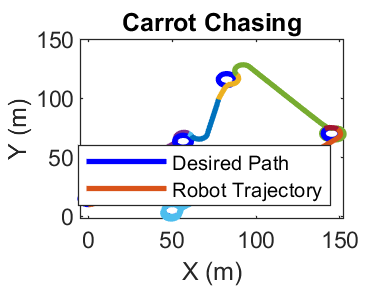

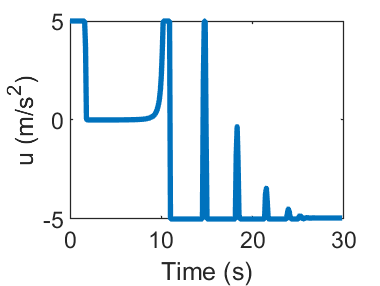

%%-------------END OF CODE---------------------------------%%
%flag=[+1,-1;+1,-1;+1,-1;-1,+1;-1,-1];
carrot_chaser;

%CCA_carrot(0, 10, 60, 60, 45, sc_1(1,1), +1);

